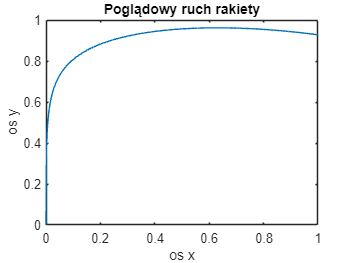


n = 1000;    % Ilość próbek
x0 = 0;     % Początek osi x
xe = 1;     % Koniec osi x
x= linspace(x0,xe, n);
y = (log10(6*x)+3.3)/3.805 - (6*x).^2/250;
y(1) = 0;
plot(x,y)
title("Poglądowy ruch rakiety")
xlabel("os x")
ylabel("os y")


dx = (xe-x0)/n;
dy = ((log10(6*(x+dx))+3.3)/3.805 - (6*(x+dx).^2/250)) - y;
cosA = dx./dy;
kat = acosd(cosA)-90;
kat(1)=0;
%{
plot(x,kat)
title("Zmiana kąta na cykl (z błędem)")
xlabel("Lp.")
ylabel("Wartość kąta")
%}

% Suma wszystkich kątów dla silnika ROT (z błędem)
suma=0;
for v=1:n
    suma = suma+kat(v);
end
suma

suma = -5.5041e+03

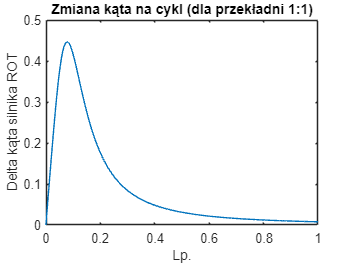

kat=kat.*90/suma;
plot(x,kat)
title("Zmiana kąta na cykl (dla przekładni 1:1)")
xlabel("Lp.")
ylabel("Delta kąta silnika ROT")


% Suma wszystkich kątów dla silnika ROT
suma=0;
for v=1:n
    suma = suma+kat(v);
end
suma

suma = 90.0000

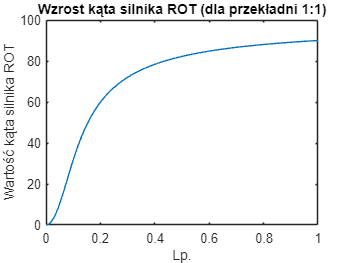



i=0;
kat_rakiety=1:n;
for z=1:n
    kat_rakiety(z)=i+kat(z);
    i=kat_rakiety(z);
end
plot(x,kat_rakiety)
title("Wzrost kąta silnika ROT (dla przekładni 1:1)")
xlabel("Lp.")
ylabel("Wartość kąta silnika ROT")

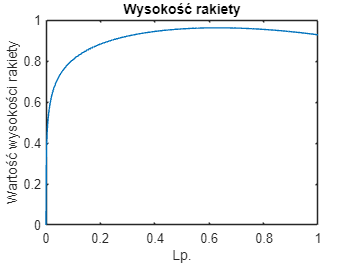


%Dla wysokości
plot(x,y)
title("Wysokość rakiety")
xlabel("Lp.")
ylabel("Wartość wysokości rakiety")

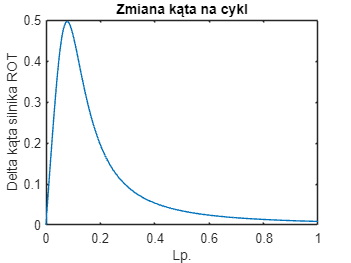


% Parametry silników
% Ilość kroków na pełny obrót
engine_rot = 200;
engine_up = 200;
% Przekładnia silnika
e_rot = 2;
e_up = 4;
% Przekładnia taśmy dla silnika up
e_up_2 = 10;
% Wynik końcowy
kat_e_rot = kat.*engine_rot*e_rot/360;
plot(x,kat_e_rot)
title("Zmiana kąta na cykl")
xlabel("Lp.")
ylabel("Delta kąta silnika ROT")

%ruch silnika
stepper_motor_list=1:n;
var = 0;
list=kat;
for i=1:n-1
    stepper_motor_list(i) = 0;
    while (list(i)*360/(engine_rot*e_rot))>=1
        stepper_motor_list(i)=stepper_motor_list(i)+1;
        list(i) = list(i)-360/(engine_rot*e_rot);
    end
    list(i+1) = list(i+1)+list(i);
end
stepper_motor_list(n) = 0;
stepper_motor_list

stepper_motor_list =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     1     0     0     0     1     0     0     0     1     0     0     0     1     0     0     1     0     0     1     0     1     0     0     1     0     0     1     0


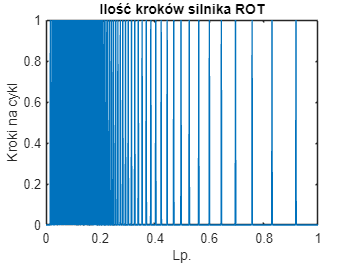

plot(x,stepper_motor_list)
title("Ilość kroków silnika ROT")
xlabel("Lp.")
ylabel("Kroki na cykl")

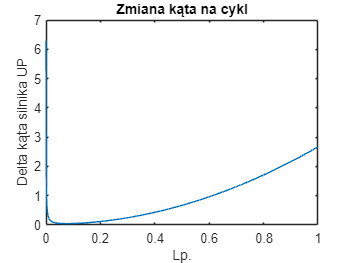


kat_e_up = dy.*engine_up*e_up*e_up_2/360;
plot(x,kat_e_up)
title("Zmiana kąta na cykl")
xlabel("Lp.")
ylabel("Delta kąta silnika UP")

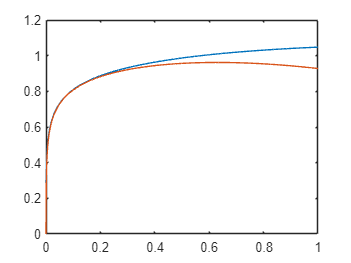


plot(x,((log10(6*(x+dx))+3.3)/3.805 - (6*(x+dx).^2/250)),x,y)


% Zapis do pliku .txt
fileID = fopen('wynik.txt','w');
for i=1:n
    fprintf( fileID, '%d, %d, %d \r', i, stepper_motor_list(i), y(i));
end
fclose(fileID);